clc
clear all
close all


# ELABORATO SERVOSYSTEMS & ROBOTICS

Link's dimentions expressed in meters:

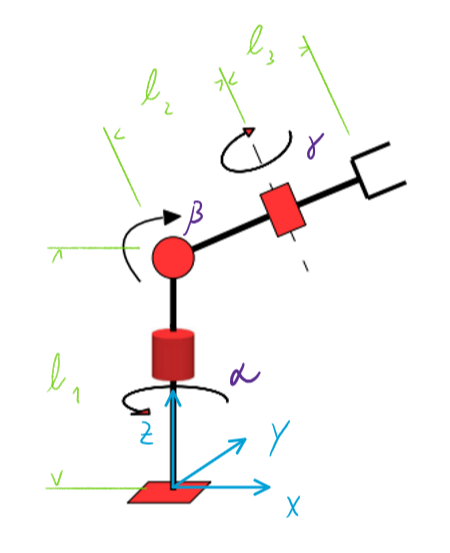

- Length of **Link 1**:

link1 = 1.2;

Link1 has a **Revolute Joint **that can freely rotate around the $z$ axis. $\alpha =\left\lbrack 0;\;2\pi \right\rbrack \ldotp$

- Length of **Link 2**:

link2 = 0.7;

Link2 has a **Revolute Joint **that can freely rotate in planes $y\;z$. $\beta =\left\lbrack 0;\;2\pi \right\rbrack$*. *

- Length of **Link 3**:

link3 = 0.4;

Link3 has a **Revolute Joint **that can freely rotate based on second link. $\gamma =\left\lbrack 0;\;2\pi \right\rbrack$.

L = [link1, link2, link3];    % matrice link
n = 500;

## Caricamento dati

% Creazione array di lavoro:

TT_TOT = [];

Q_TOT = [];
QP_TOT = [];
QPP_TOT = [];

S_TOT = [];
SP_TOT = [];
SPP_TOT = [];

CC1_TOT= [];
CC2_TOT = [];
CC3_TOT = [];

EK_TOT = [];
EP_TOT = [];
E_TOT = [];

WW_TOT = [];
P_TOT = [];



% Caricamento dati realativi al primo tratto:

load dati1.mat       % dati ricavati dal primo tratto


% Inserimento dati primo tratto in array totali:

T = tt(end);
TT_TOT = [TT_TOT tt];

Q_TOT = [Q_TOT Q];
QP_TOT = [QP_TOT Qp];
QPP_TOT = [QPP_TOT Qpp];

S_TOT = [S_TOT S];
SP_TOT = [SP_TOT Sp];
SPP_TOT = [SPP_TOT Spp];

CC1_TOT= [CC1_TOT CC1];
CC2_TOT = [CC2_TOT CC2];
CC3_TOT = [CC3_TOT CC3];

EK_TOT = [EK_TOT EK_tot];
EP_TOT = [EP_TOT EP_tot];
E_TOT = [E_TOT E_tot];

WW_TOT = [WW_TOT WW_tot];
P_TOT = [P_TOT P_tot];



% Caricamento dati realativi al tratto centrale:

load dati2.mat       % dati ricavati da tratto centrale


% Inserimento dati tratto centrale in array totali:

tt = tt+T;
T = tt(end);
TT_TOT = [TT_TOT tt];

Q_TOT = [Q_TOT Q];
QP_TOT = [QP_TOT Qp];
QPP_TOT = [QPP_TOT Qpp];

S_TOT = [S_TOT S1];
SP_TOT = [SP_TOT Sp1];
SPP_TOT = [SPP_TOT Spp1];

CC1_TOT= [CC1_TOT CC1];
CC2_TOT = [CC2_TOT CC2];
CC3_TOT = [CC3_TOT CC3];

EK_TOT = [EK_TOT EK_tot];
EP_TOT = [EP_TOT EP_tot];
E_TOT = [E_TOT E_tot];

WW_TOT = [WW_TOT WW_tot];
P_TOT = [P_TOT P_tot];



% Caricamento dati realativi al tratto finale:

load dati3.mat       % dati ricavati dal tratto finale


% Inserimento dati tratto finale in array totali:

tt = tt+T;
T = tt(end);
TT_TOT = [TT_TOT tt];

Q_TOT = [Q_TOT Q];
QP_TOT = [QP_TOT Qp];
QPP_TOT = [QPP_TOT Qpp];

S_TOT = [S_TOT S];
SP_TOT = [SP_TOT Sp];
SPP_TOT = [SPP_TOT Spp];

CC1_TOT= [CC1_TOT CC1];
CC2_TOT = [CC2_TOT CC2];
CC3_TOT = [CC3_TOT CC3];

EK_TOT = [EK_TOT EK_tot];
EP_TOT = [EP_TOT EP_tot];
E_TOT = [E_TOT E_tot];

WW_TOT = [WW_TOT WW_tot];
P_TOT = [P_TOT P_tot];


- Rimozione Elementi Doppi

TT_TOT = TT_TOT([1:(n-1), (n+1):(3*n-1), (3*n+1):end]);

Q_TOT = Q_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
QP_TOT = QP_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
QPP_TOT = QPP_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));

S_TOT = S_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
SP_TOT = SP_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
SPP_TOT = SPP_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));

CC1_TOT = CC1_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
CC2_TOT = CC2_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
CC3_TOT = CC3_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));

EK_TOT = EK_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
EP_TOT = EP_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
E_TOT = E_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));

WW_TOT = WW_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));
P_TOT = P_TOT(:,([1:(n-1), (n+1):(3*n-1), (3*n+1):end]));

## Plot tutti i grafici

**2.1 PLOT**:

- Plot configurations:

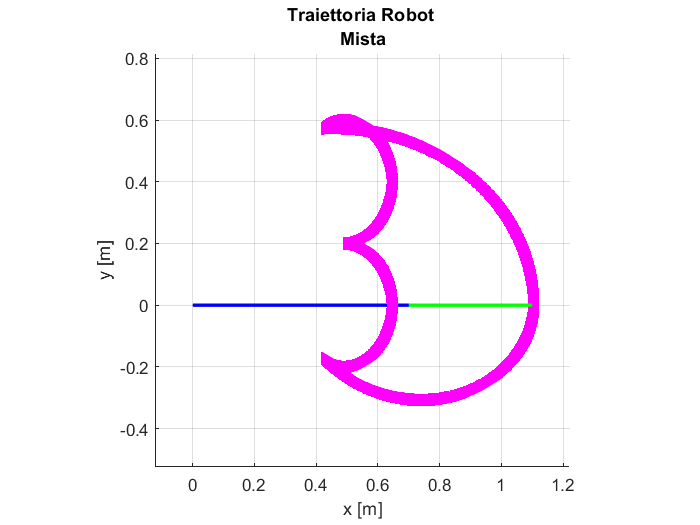

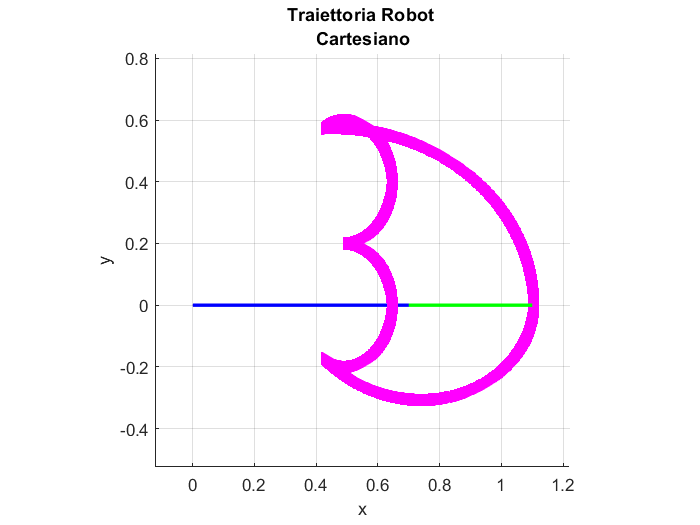

%% plot configurations
n = length(TT_TOT);
% Dati da cinematica diretta:
%Plot_Trajectory_AAA(Q_TOT(:,1),Q_TOT(:,end),L,S_TOT(1,:),S_TOT(2,:),S_TOT(3,:),n,"Mista",T);
%Plot_Trajectory_animation_AAA(Q_TOT,S_TOT,L,length(S_TOT(1,:)),TT_TOT(end),"Cartesiano")

- Plot graph of data x,y,z position speed and acceleration direct kinematics:

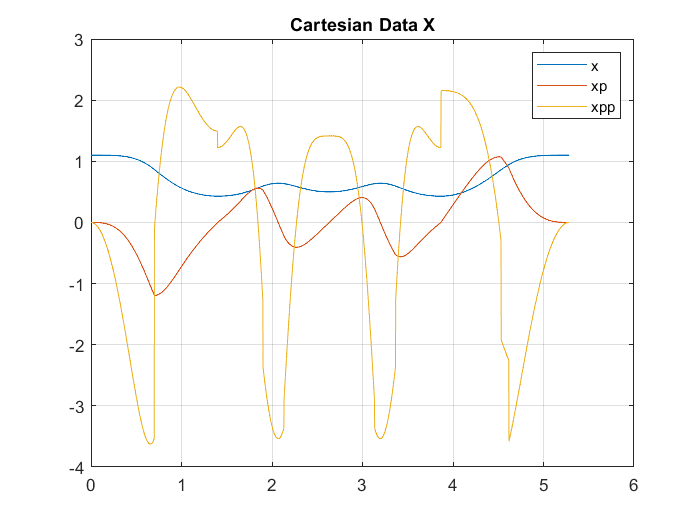

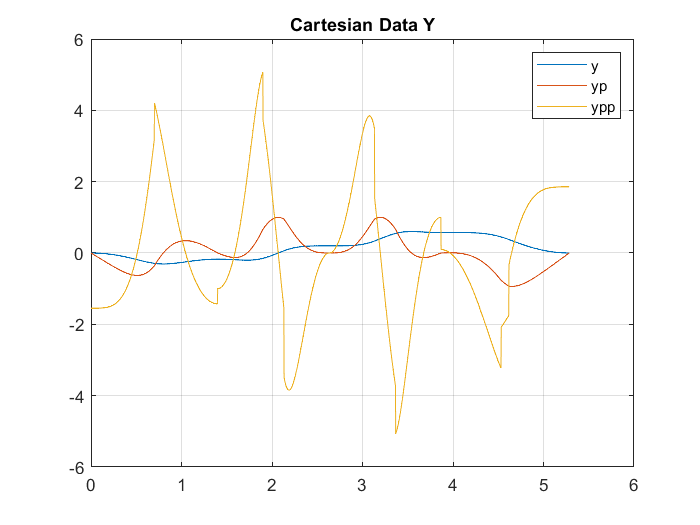

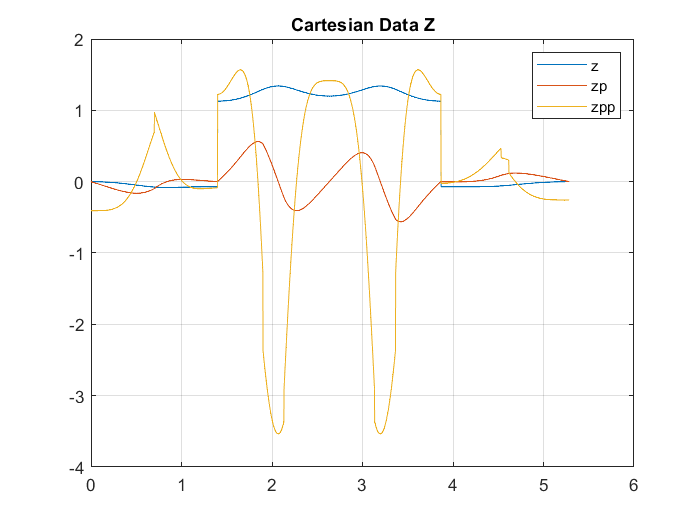

Plot_Graphs_Dir_Kinematics_noDebug_AAA(S_TOT,SP_TOT,SPP_TOT,TT_TOT)

- Plot Coppie:

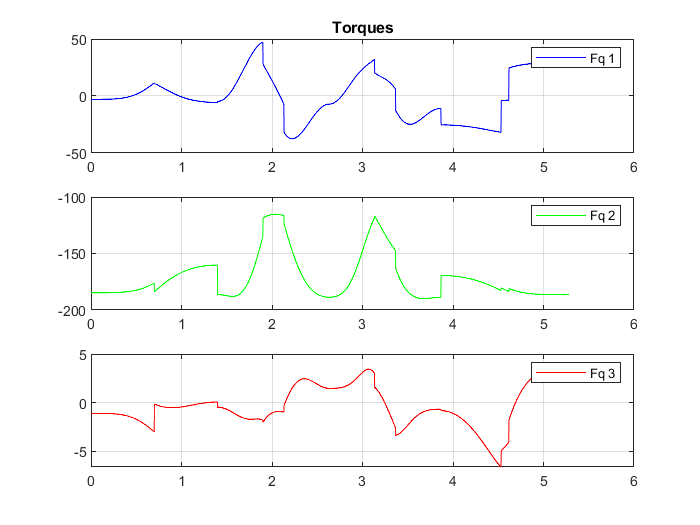

h = figure;
set(h,'name','torques')
subplot(3,1,1)
plot(TT_TOT,CC1_TOT,'b')
legend("Fq 1")
grid on
title("Torques")

subplot(3,1,2)
plot(TT_TOT,CC2_TOT,'g')
legend("Fq 2")
grid on

subplot(3,1,3)
plot(TT_TOT,CC3_TOT,'r')
legend("Fq 3")
grid on

- Plot Energia:

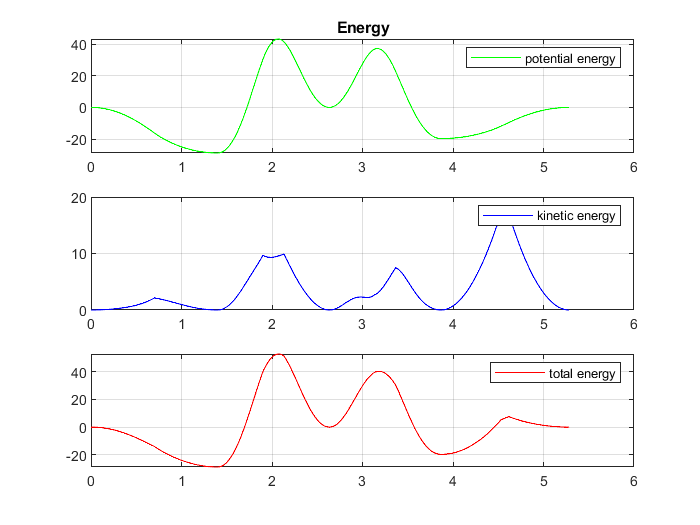

h = figure;
set(h,'name','energy') 

subplot(3,1,1)
plot(TT_TOT,EP_TOT,'g')
legend("potential energy")
grid on
title("Energy")

subplot(3,1,2)
plot(TT_TOT,EK_TOT,'b')
legend("kinetic energy")
grid on

subplot(3,1,3)
plot(TT_TOT,E_TOT,'r')
legend("total energy")
grid on

- Plot Potenze reali e teoriche:

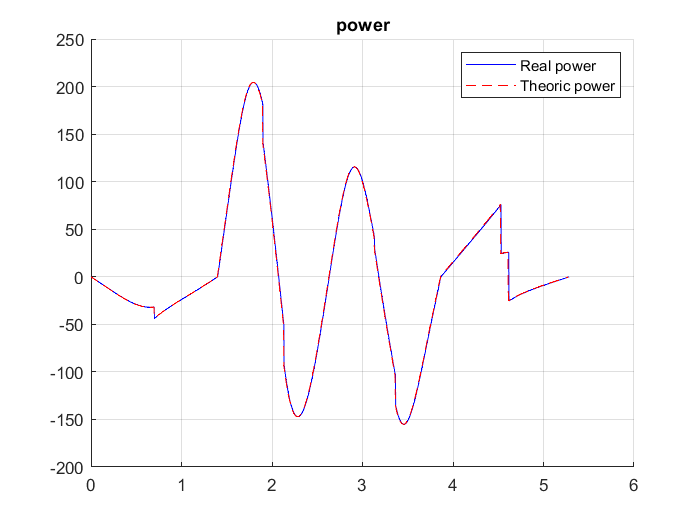

h = figure;
set(h,'name','power') 
hold on
grid on
plot(TT_TOT,WW_TOT,'b')

plot(TT_TOT(1:length(P_TOT)),P_TOT,'r--')
legend("Real power", "Theoric power")
title("power")

## Salvataggio Dati per simulink

save dati_TOT L Q_TOT QP_TOT QPP_TOT S_TOT SP_TOT SPP_TOT CC1_TOT CC2_TOT CC3_TOT EP_TOT EK_TOT E_TOT WW_TOT P_TOT TT_TOT

## Simulink Comparison

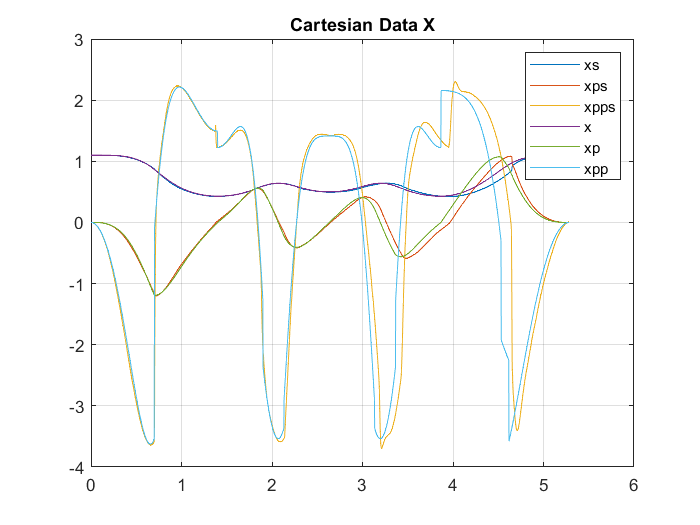

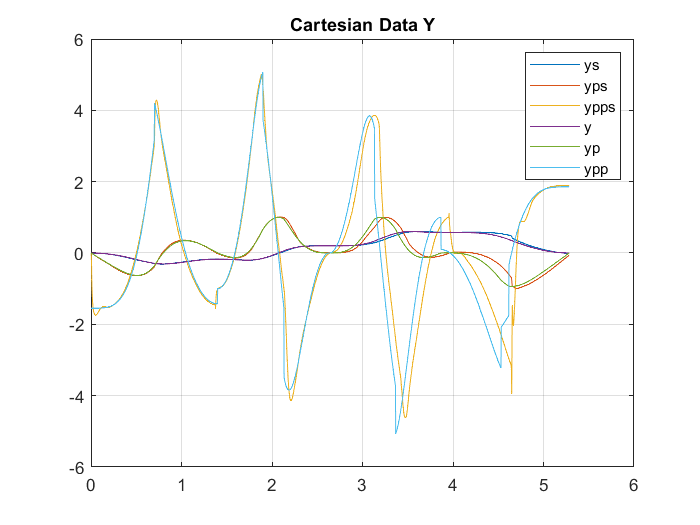

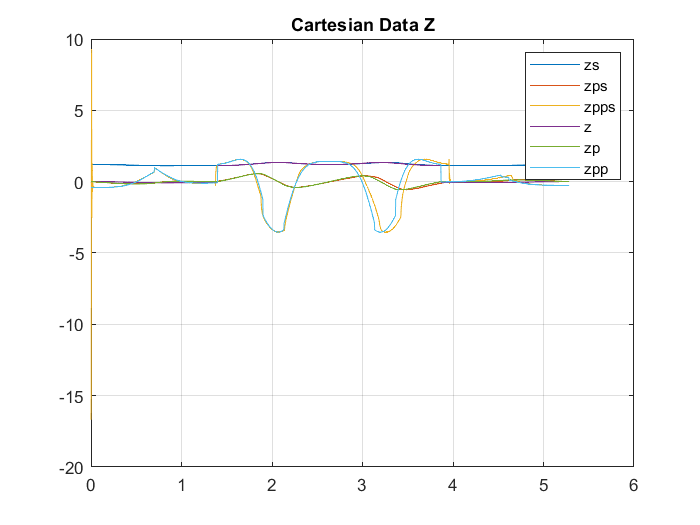

tt_new = linspace(0,TT_TOT(end),length(out.CC_Real(:,1)));

Plot_Graphs_Dir_Kinematics_Debug_Simulink_AAA(out.S_Real',out.SP_Real',out.SPP_Real',tt_new,S_TOT,SP_TOT,SPP_TOT,TT_TOT);

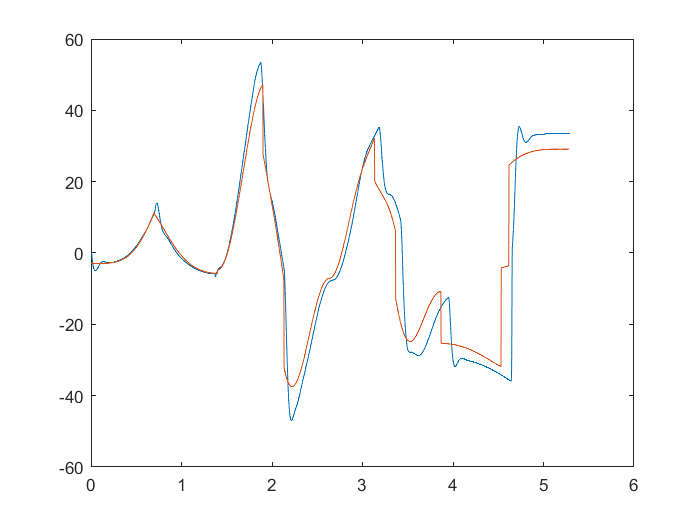


plot(tt_new,out.CC_Real(:,1),TT_TOT,CC1_TOT)

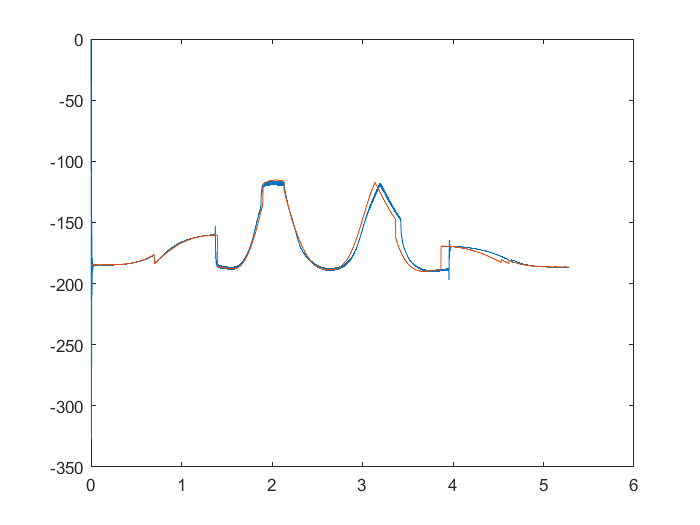

plot(tt_new,out.CC_Real(:,2),TT_TOT,CC2_TOT)

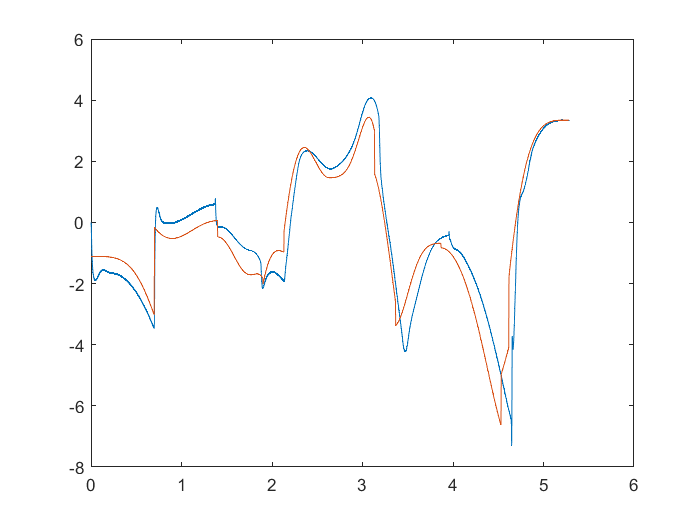

plot(tt_new,out.CC_Real(:,3),TT_TOT,CC3_TOT)